# **Uninfected**

## **GLOBULOS BLANCOS**

### **a) Anotaciones**

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Uninfected Patients\TF201_HT6\tiled'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.tiff'));

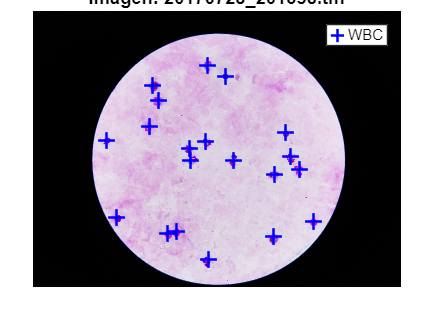

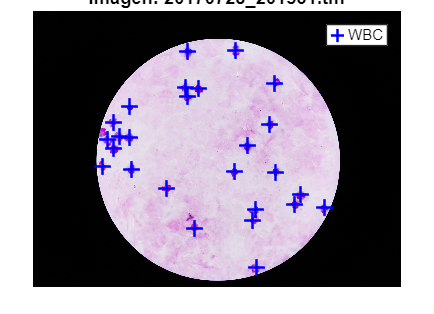

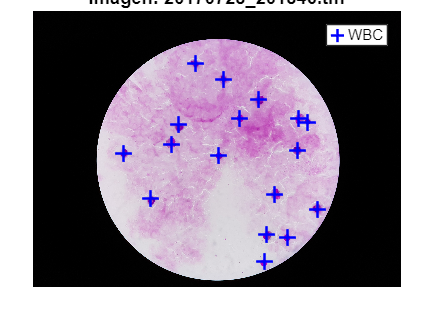

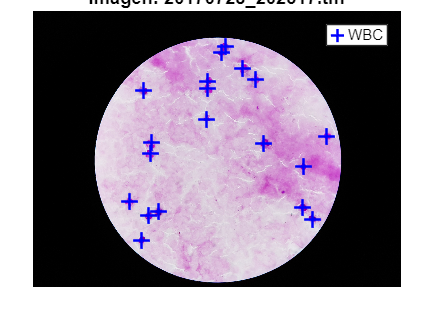

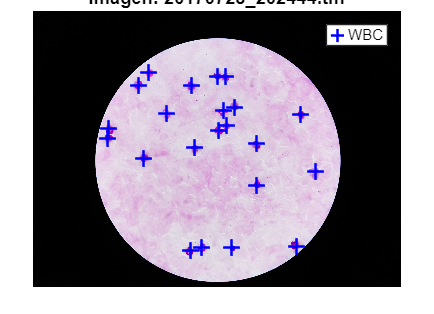

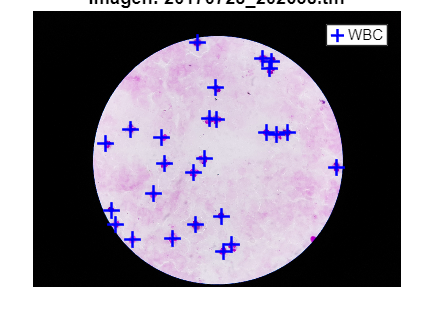

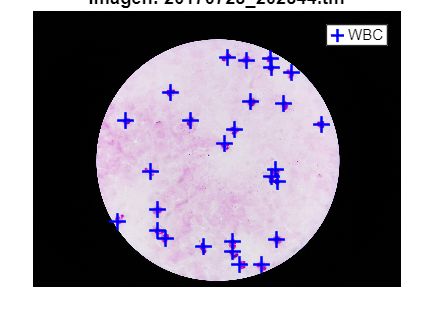

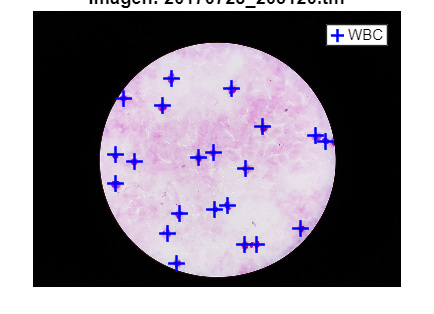

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Annotations\TF201_HT6\results\2546', [imageFiles(i).name(1:end-5), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('WBC');
    hold off;
end

## **PARÁSITOS**

**No debería de haber**

### a) 4º Modelo Canny

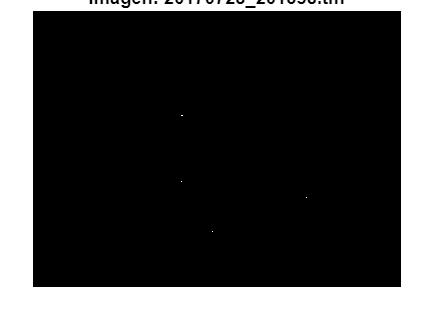

ruido = 16

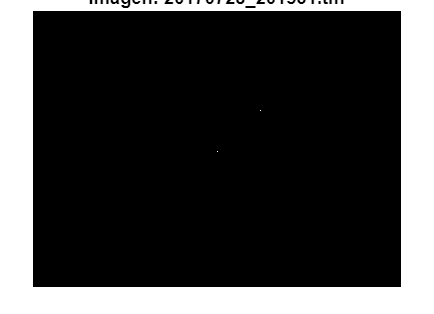

ruido = 2

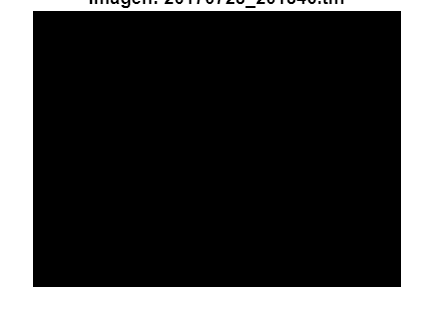

ruido = 1

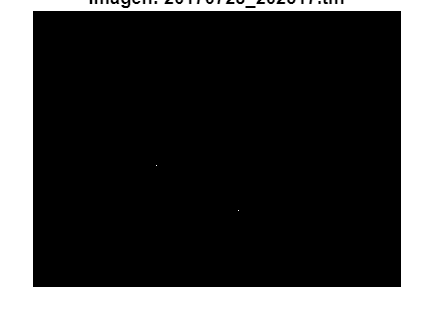

ruido = 8

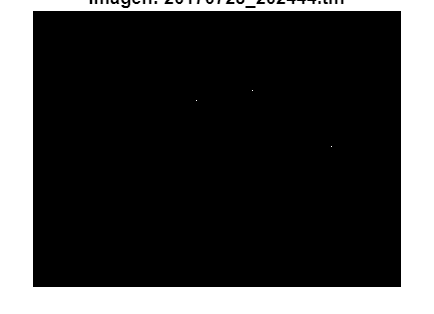

ruido = 4

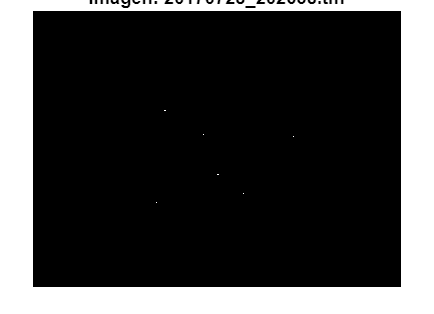

ruido = 13

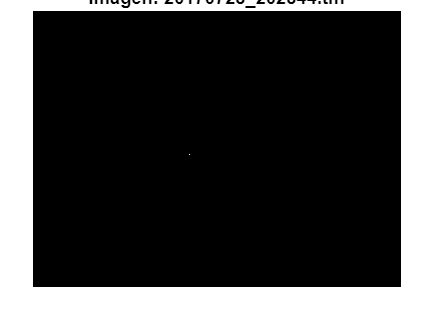

ruido = 1

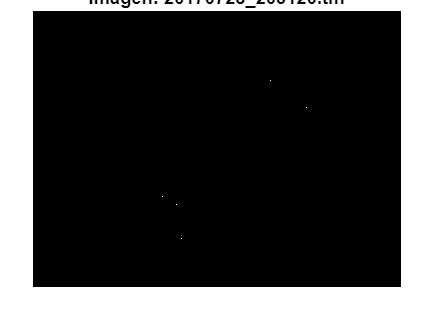

ruido = 11

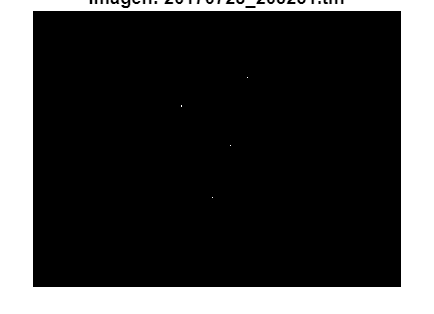

ruido = 11

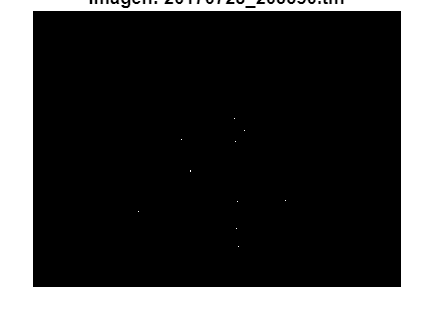

ruido = 18

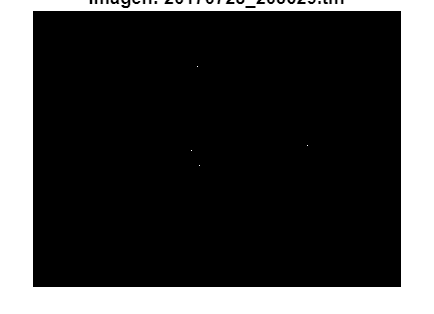

ruido = 10

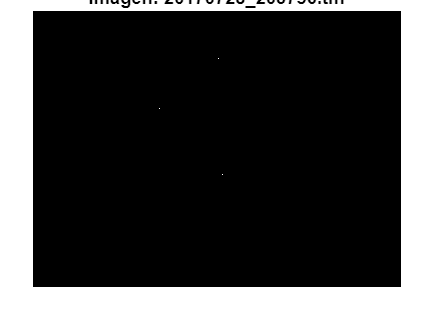

ruido = 8

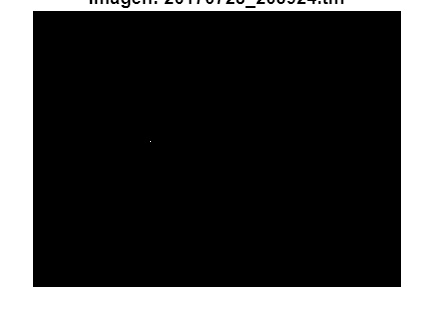

ruido = 2

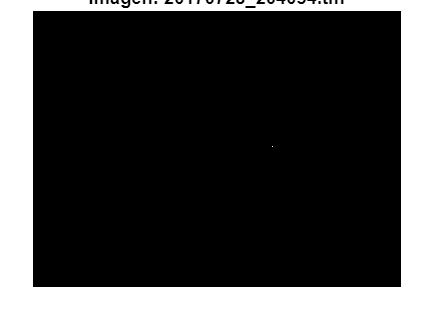

ruido = 1

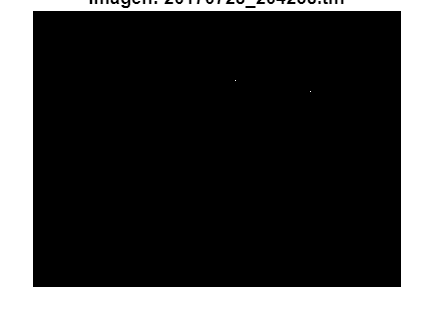

ruido = 6

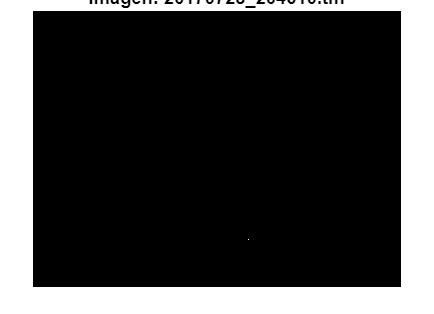

ruido = 3

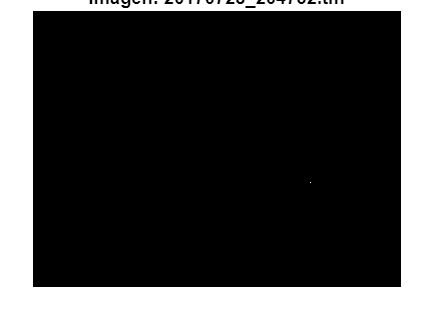

ruido = 2

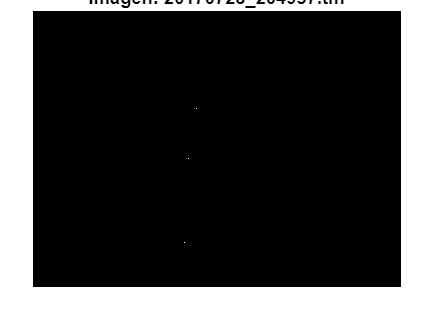

ruido = 7

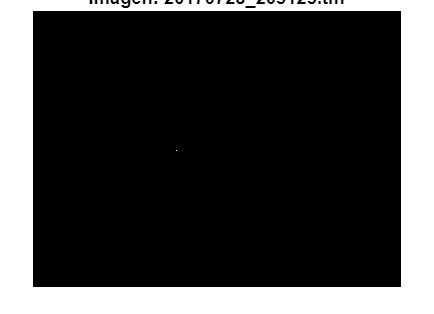

ruido = 3

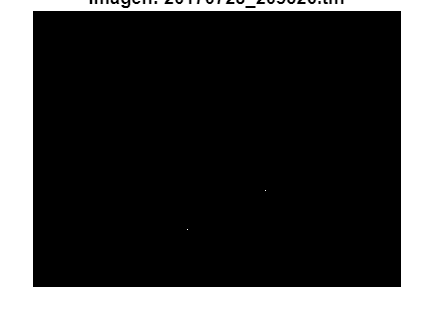

ruido = 9

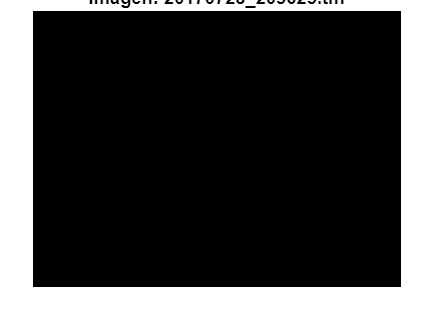

ruido = 1

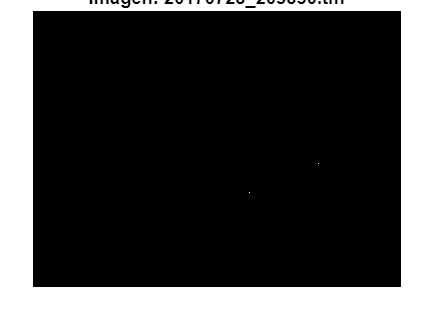

ruido = 2

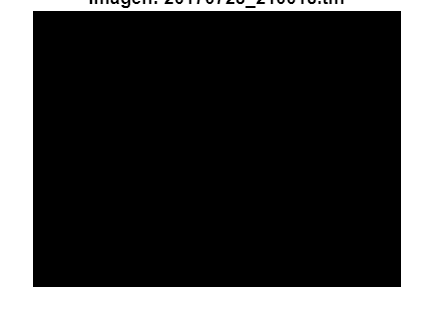

ruido = 1

total_ruido=0;
cantidad_imagenes_ruido=0;
for i = 1:length(imageFiles)
    % Fitxategiaren izen osoa
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
  
    % Pasarlo a escala de grises
    I_gray = rgb2gray(I);

    % Quitar ruido
    I_sinruido=medfilt2(I_gray, [3 3]);
    
    % Detección de bordes
    BW = edge(I_sinruido, 'Canny',[0.05 0.4]);
    
    % Cerrar los contornos
    BW = imclose(BW, strel('disk', 40));
    
    % Revisar las propiedades
    CC = bwconncomp(BW,8);
    properties = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    stats = regionprops(CC,properties);
    
    % Define umbrales de área
    area_min = 200;
    area_max = max([stats.Area]); 
    
    % Crear nueva máscara basada en área
    BW_filtrada_area = false(size(BW));
    labeled_area = labelmatrix(CC);
    
    for c = 1:length(stats)
        area = stats(c).Area;
     
        if area >= area_min && area <= area_max
            BW_filtrada_area = BW_filtrada_area | (labeled_area == c);
        end
    end
    
    % Reemplazar máscara con la filtrada por área
    globulos_blancos = BW_filtrada_area;

    % Mascara de parasitos
    mascara_parasitos=BW-globulos_blancos;

    % Visualiza la máscara final
    figure;
    imshow(mascara_parasitos);
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    
    % Mirar las propiedades de los pixeles
    n=8; % neighbourhood

    % Contar puntos detectados
    CC = bwconncomp(mascara_parasitos,n);
    properties = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC,properties);
    ruido=size(caracteristicas,1)
    total_ruido=total_ruido+ruido;
    if ruido>=1
        cantidad_imagenes_ruido=cantidad_imagenes_ruido+1;
    end
end

total_ruido

total_ruido = 140

cantidad_imagenes=length(imageFiles)

cantidad_imagenes = 23

media=total_ruido/cantidad_imagenes

media = 6.0870